clc;
clear;

Z0=150;
Zl=250+1i*100;
fmin=6e8;                           
fmax=1.4e9;                         
fstep=1e6;                          
c=3e8;                             
f0=(fmin+fmax)/2;                   
lamuta=c/f0;                        
freq=fmin:fstep:fmax;               

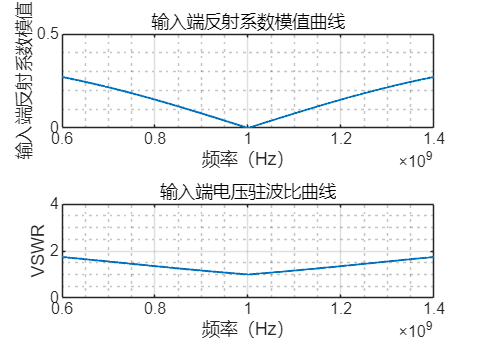

[T1,fai,L1,p1,Z01,Zin2,T2,p2]=impedance_transformer(Z0,Zl,lamuta,freq,c,f0);
figure(1);
subplot(2,1,1);
plot(freq,abs(T2) ,'LineWidth',1);             %反射系数模值频率特性
title('输入端反射系数模值曲线');
xlabel('频率（Hz）');
ylabel('输入端反射系数模值');
axis([fmin fmax 0 0.5]);
grid minor;
grid on;

subplot(2,1,2);
plot(freq, p2,'LineWidth',1);             %驻波比频率特性
title('输入端电压驻波比曲线');
xlabel('频率（Hz）');
ylabel('VSWR');
axis([fmin fmax 0 4]);
grid minor;
grid on;

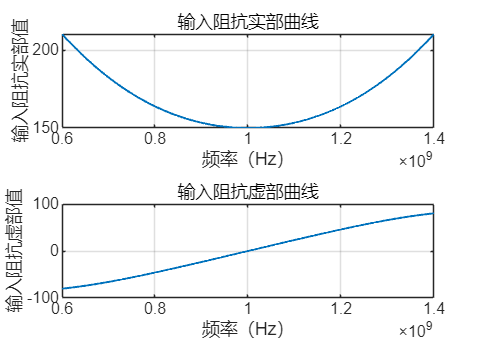


figure(2);
subplot(2,1,1)
plot(freq,real(Zin2) ,'LineWidth',1)                %输入阻抗实部频率特性
title('输入阻抗实部曲线');
xlabel('频率（Hz）');
ylabel('输入阻抗实部值');
grid on;
subplot(2,1,2)                      %输入阻抗虚部频率特性
plot(freq,imag(Zin2) ,'LineWidth',1) 
title('输入阻抗虚部曲线');
xlabel('频率（Hz）');
ylabel('输入阻抗虚部值');
grid on;


function Zin=input_impedance(Z0,thate,Zl)
Zin=Z0.*(Zl+1i*Z0.*tan(thate))./(Z0+1i*Zl.*tan(thate));
end

function [T1,fai,L1,p1,Z01,Zin2,T2,p2]=impedance_transformer(Z0,Zl,lamuta,freq,c,f0)
T1=(Zl-Z0)/(Zl+Z0);                      
fai=angle(T1);                           
if(imag(Zl)>=0)
    L1=lamuta*fai/(4*pi);                
elseif(imag(Zl)<0)
    L1=lamuta*fai/(4*pi)+lamuta/4;       
end
p1=(1+abs(T1))/(1-abs(T1));              
Z01=Z0*sqrt(p1);                         
thata1=L1*2*pi*freq/c;              
Zin1=input_impedance(Z0,thata1,Zl);      
thata2=2*pi*freq/f0/4;                   
Zin2=input_impedance(Z01,thata2,Zin1); 
T2=(Zin2-Z0)./(Zin2+Z0);                 
p2=(1+abs(T2))./(1-abs(T2));             
end